## 2. Classificació automàtica d’espècies arbòries

Joan Manuel Ramos Refusta + Borja Cantero Aranda

## Experimentos realizados

Primero de todo hemos realizado la obtención de todas las transformadas de fourier y obtener el vector mínimo de estas. Ya que la tabla que utilizaremos para los modelos de clasificación ha de contener todos los vectores de las transformadas y han de ser del mismo tamaño. Por lo tanto, hemos tenido que encontrar el limite máximo donde se puede crear la tabla para las 48 hojas.

A continuación, hemos utilizado la app Classification Learner para realizar diferentes clasificaciones modificando el número de descriptores (0 < N <= 1328).

Queriamos observar como influia este valor en los porcentajes de acierto.

Hemos utilizado la opción de utilizar todos los modelos disponibles de clasificadores

## Código para obtener los descriptores de todas las hojas

%El valor de N es modificable, este valor indica con cuantos números de
%descriptores se tratará durante el entrenamiento de los diferentes modelos
%Como máximo se puede poner un valor de 1328 ya que se ha encontrado 


%con 1328
%83.3 fine tree
%75.0 bayes gaussian
%81.3 ensambled knn

%con 650
% 64.5 fine tree
% 77.0 bayes gaussian
% 83.3 ensambled knn

% con 50
% 81.3 fine tree
% 85.4 bayes gaussian
% 77.1 ensambled knn

% con 50 con 6 features: M2, M4, M11, M21, M23
% 91.7 fine tree
N = 50;
M = zeros(48, N);

for i = 1:16
    k = string(i);
    f = (i-1)*3;
    %Leemos las imagenes de las carpetas
    ime = imread('Erable\' + k + '.jpg');
    imf = imread('Faig\' + k + '.jpg');
    imr = imread('Roure\' + k + '.jpg');
    
    %Pasamos la imagen a binario
    bw = imcomplement(im2bw(ime));
    
    %Mantenemos el contorno del cual obtendremos la transformada de fourier
    ee = strel('disk', 5);
    bw = imclose(bw,ee);
    bw = imopen(bw,ee);
    
    %Se intenta eliminar el tallo de la hoja
    ee = strel('disk', 1);
    ero=imerode(bw,ee);
    cont=xor(ero,bw);
    
    [fila col] = find(bw,1); % Buscamos el primer pixel
    B = bwtraceboundary(bw,[fila col],'E'); %ddireccion este al azar
    
    mig=mean(B);
    B(:,1)=B(:,1)-mig(1);
    B(:,2)=B(:,2)-mig(2);
    % Convertimos las coordenadas a complejas
    s= B(:,1) + i*B(:,2);
    % Hce falta que la dimensión del vector sea par
    [mida bobo]=size(B);
    if(mida/2~=round(mida/2))
    s(end+1,:)=s(end,:); %duplicamos el último
    mida=mida+1;
    end
    
    z=fft(s);% Calculamos la Fast Fourier Transform 
    %Como no se pueden tratar los modelos con valores complejos, obtenemos valores absolutos
    z=abs(z);
    %Pasamos el vector de fourier de la hoja a una matriz que contendrá
    %todas las transformadas de fourier
    M(f+1,1:N) = transpose(cat(1,z(1:N/2),z(end-(N-1)/2:end)));
    
    
    %Se repite el proceso para una hoja de roure y faig a continuación
    bw = imcomplement(im2bw(imf));
    
    ee = strel('disk', 5);
    bw = imclose(bw,ee);
    bw = imopen(bw,ee);

    ee = strel('disk', 1);
    ero=imerode(bw,ee);
    cont=xor(ero,bw);
    
    [fila col] = find(bw,1); % Busquem el primer píxel
    B = bwtraceboundary(bw,[fila col],'E'); %direccio est a l'atzar
    
    mig=mean(B);
    B(:,1)=B(:,1)-mig(1);
    B(:,2)=B(:,2)-mig(2);
    % Convertim les coordenades a complexes
    s= B(:,1) + i*B(:,2);
    % Cal que la dimensio del vector sigui parell
    [mida bobo]=size(B);
    if(mida/2~=round(mida/2))
    s(end+1,:)=s(end,:); %dupliquem l'ultim
    mida=mida+1;
    end
    % Calculem la Fast Fourier Transform
    z=fft(s);
    z=abs(z);
    M(f+2,1:N) = transpose(cat(1,z(1:N/2),z(end-(N-1)/2:end)));
    
    bw = imcomplement(im2bw(imr));
    
    ee = strel('disk', 5);
    bw = imclose(bw,ee);
    bw = imopen(bw,ee);

    ee = strel('disk', 1);
    ero=imerode(bw,ee);
    cont=xor(ero,bw);

    
    [fila col] = find(bw,1); % Busquem el primer píxel
    B = bwtraceboundary(bw,[fila col],'E'); %direccio est a l'atzar
    
    mig=mean(B);
    B(:,1)=B(:,1)-mig(1);
    B(:,2)=B(:,2)-mig(2);
    % Convertim les coordenades a complexes
    s= B(:,1) + i*B(:,2);
    % Cal que la dimensio del vector sigui parell
    [mida bobo]=size(B);
    if(mida/2~=round(mida/2))
    s(end+1,:)=s(end,:); %dupliquem l'ultim
    mida=mida+1;
    end
    % Calculem la Fast Fourier Transform
    z=fft(s);
    z=abs(z);
    M(f+3,1:N) = transpose(cat(1,z(1:N/2),z(end-(N-1)/2:end)));
end


%Transformamos la matriz que contiene todas las transformadas de fourier en
%una tabla
T = array2table(M);

%Creamos un vector con los nombres de cada tipo de hoja en la matriz
for i = 0:15
    typeFulla((i*3)+1:(i*3)+3) = ["erable","faig","roure"];    
end

%Añadimos el nombre de cada hoja a la tabla
T = addvars(T,transpose(typeFulla),'After','M' + string(N));

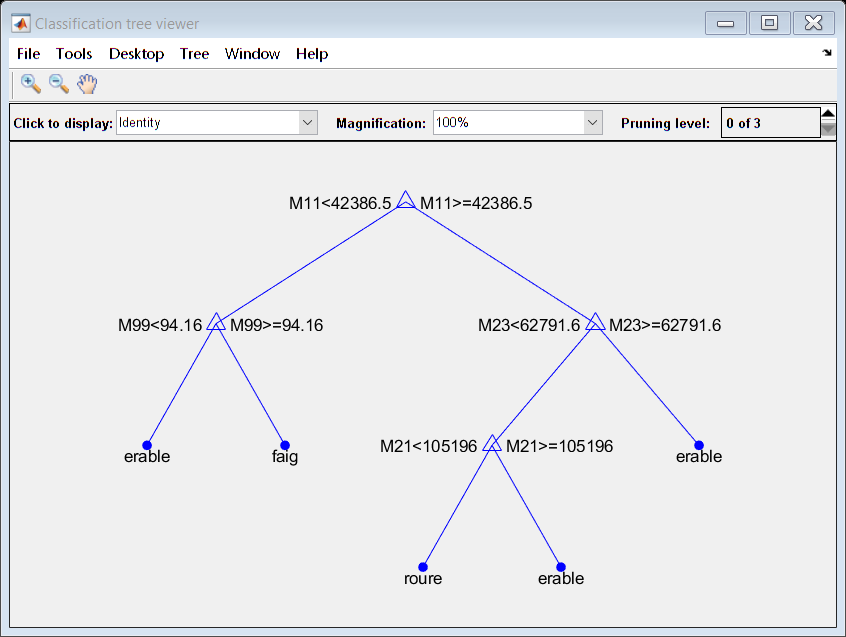

view(trainedModel.ClassificationTree,'Mode','graph');

view(trainedModel1.ClassificationTree,'Mode','graph');

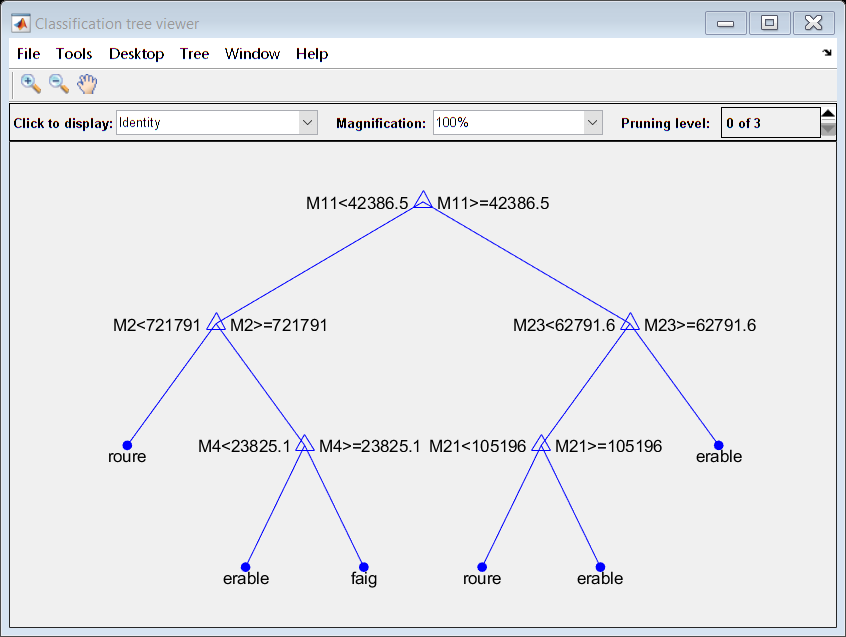

view(trainedModel2.ClassificationTree,'Mode','graph');

## Amb N = 1328

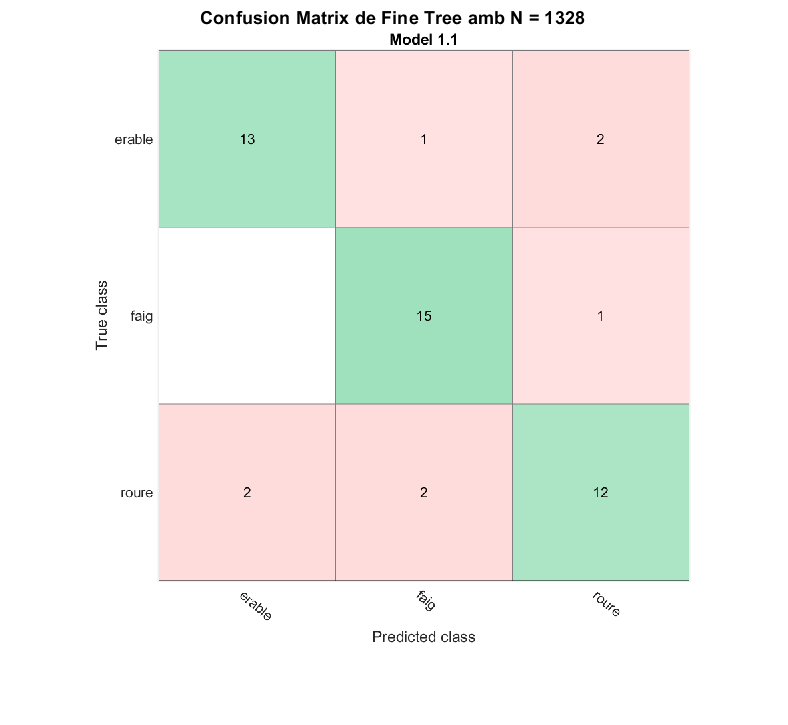

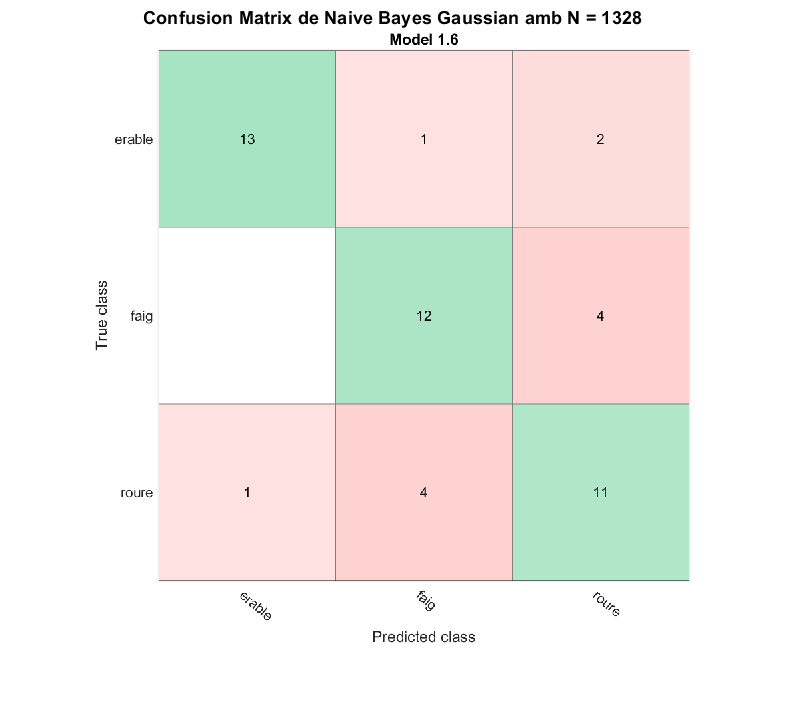

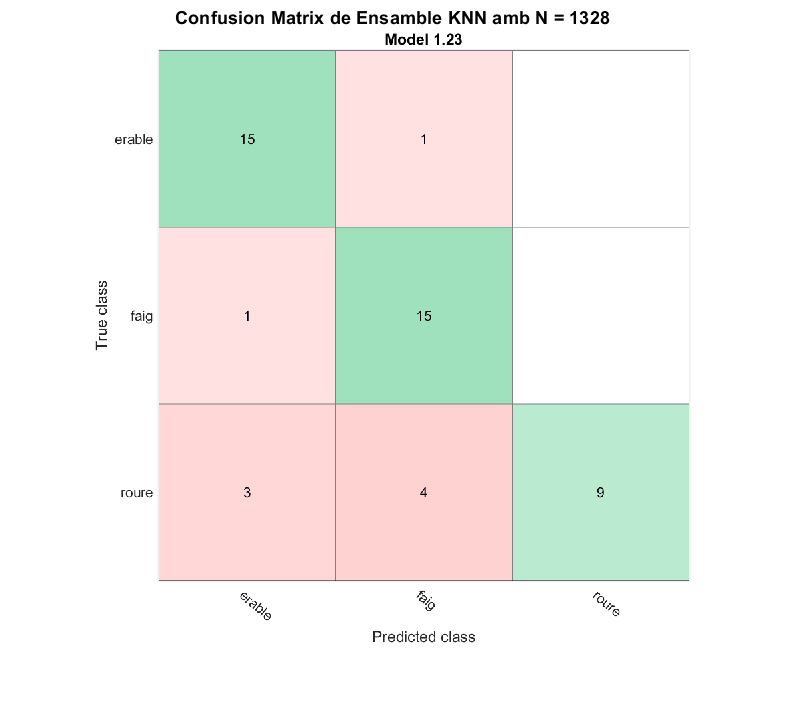

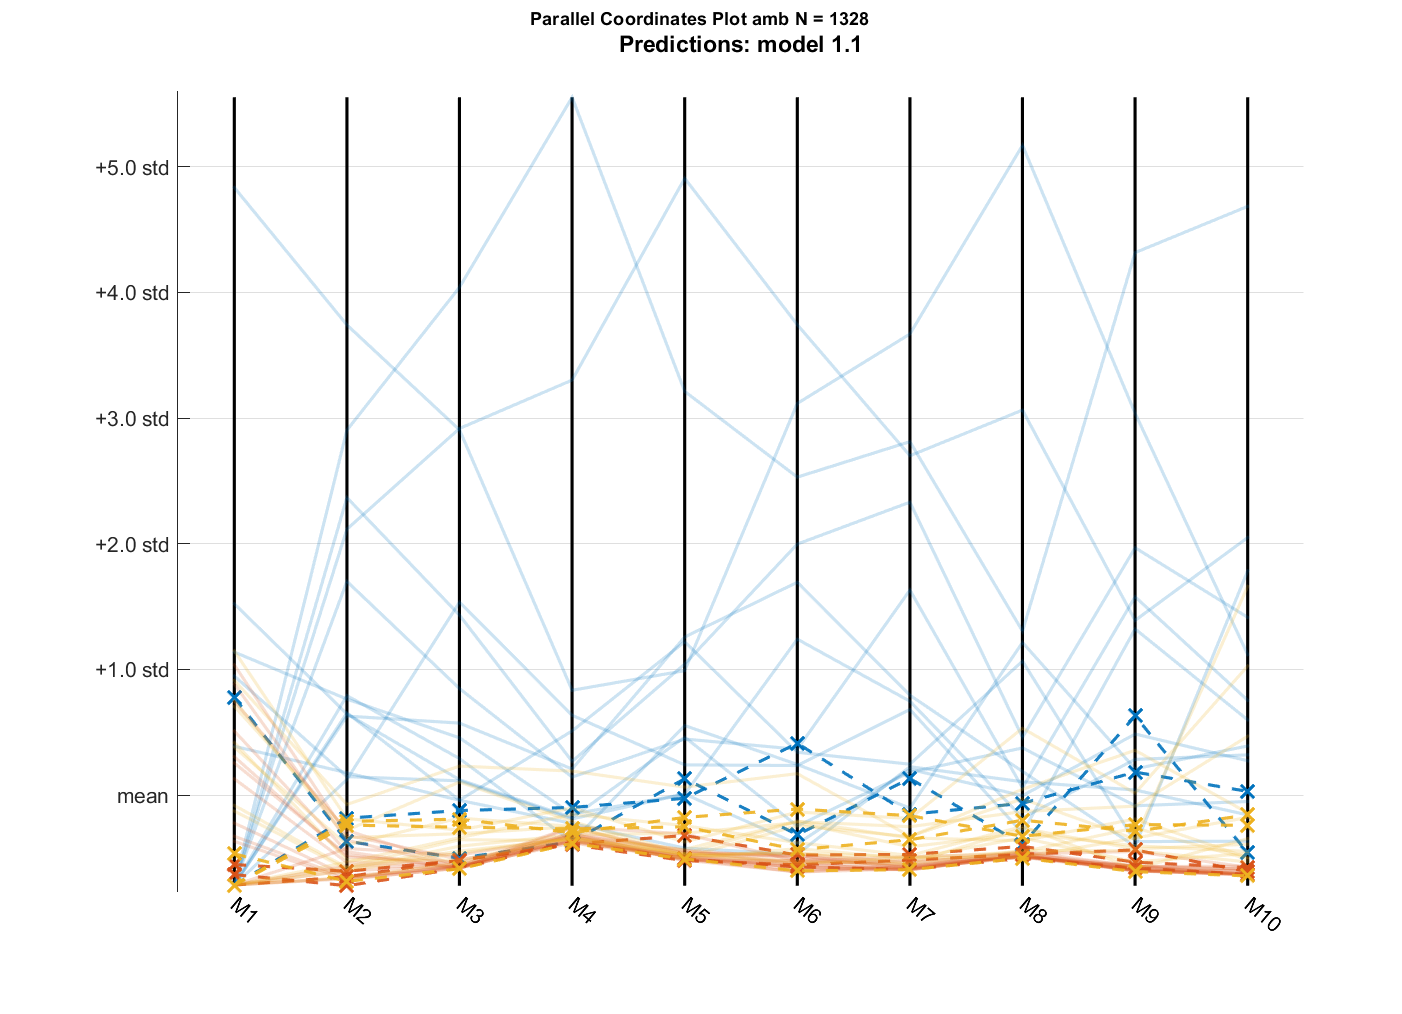

im = imread("ConfusionTree1328.png");
imshow(im);
title("Confusion Matrix de Fine Tree amb N = 1328");

im = imread("ConfusionBayes1328.png");
imshow(im);
title("Confusion Matrix de Naive Bayes Gaussian amb N = 1328");

im = imread("ConfusionEnsamble1328.png");
imshow(im);
title("Confusion Matrix de Ensamble KNN amb N = 1328");

im = imread("ParallelTree1328.png");
imshow(im);
title("Parallel Coordinates Plot amb N = 1328");

## Amb N = 650

im = imread("ConfusionTree650.png");
imshow(im);
title("Confusion Matrix de Fine Tree amb N = 650");

im = imread("ConfusionBayes650.png");
imshow(im);
title("Confusion Matrix de Naive Bayes Gaussian amb N = 650");

im = imread("ConfusionEnsamble650.png");
imshow(im);
title("Confusion Matrix de Ensamble KNN amb N = 650");

im = imread("ParallelTree650.png");
imshow(im);
title("Parallel Coordinates Plot amb N = 650");

## Amb N = 50

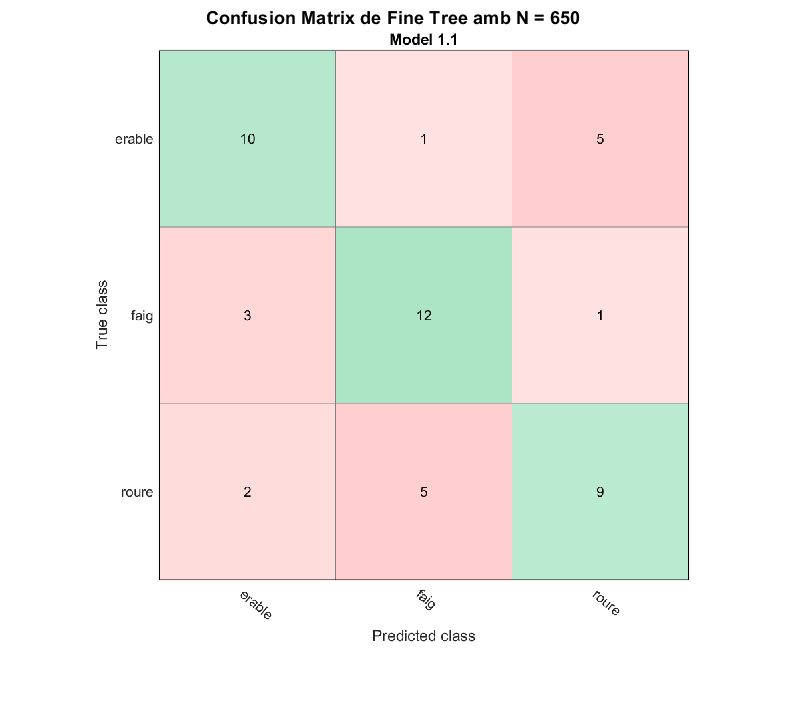

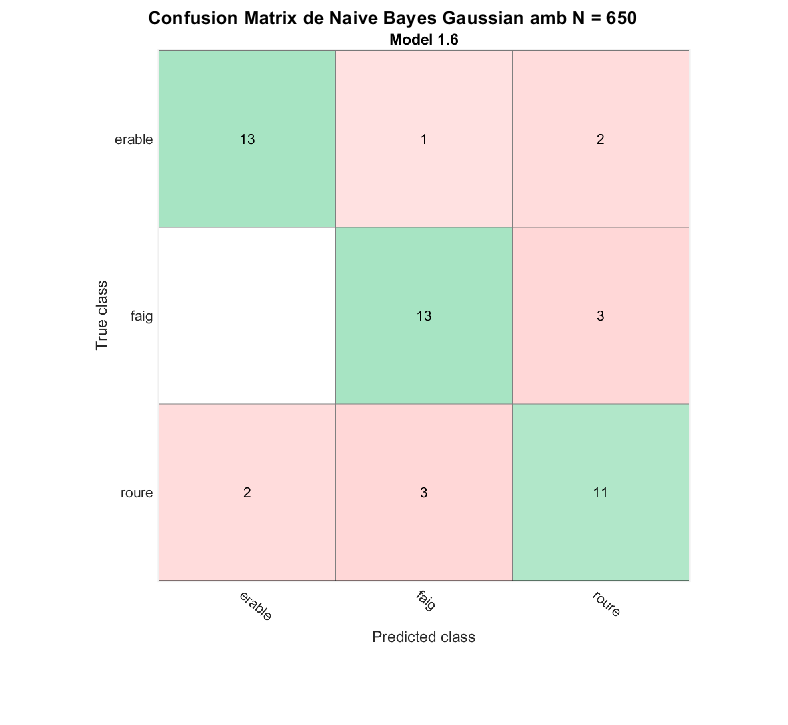

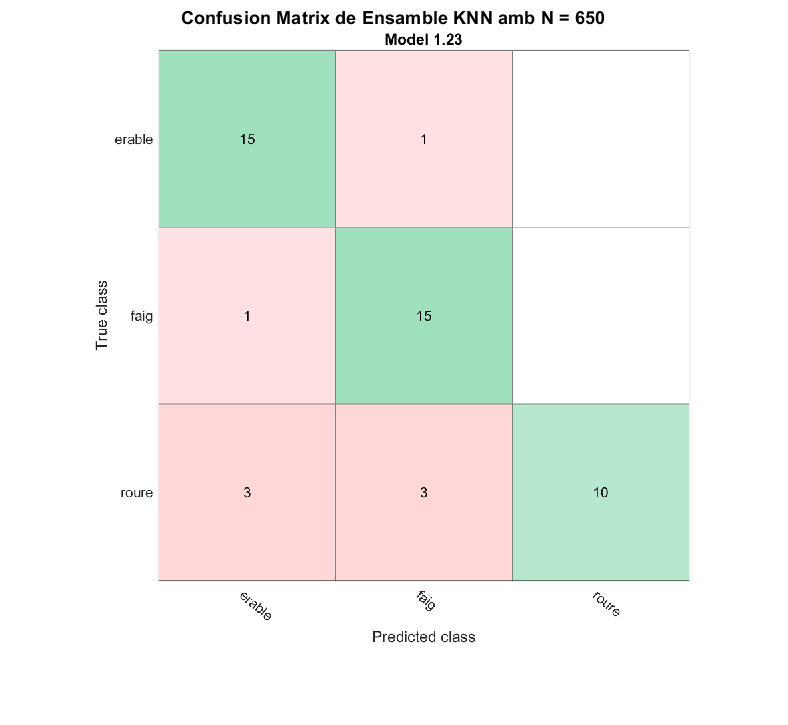

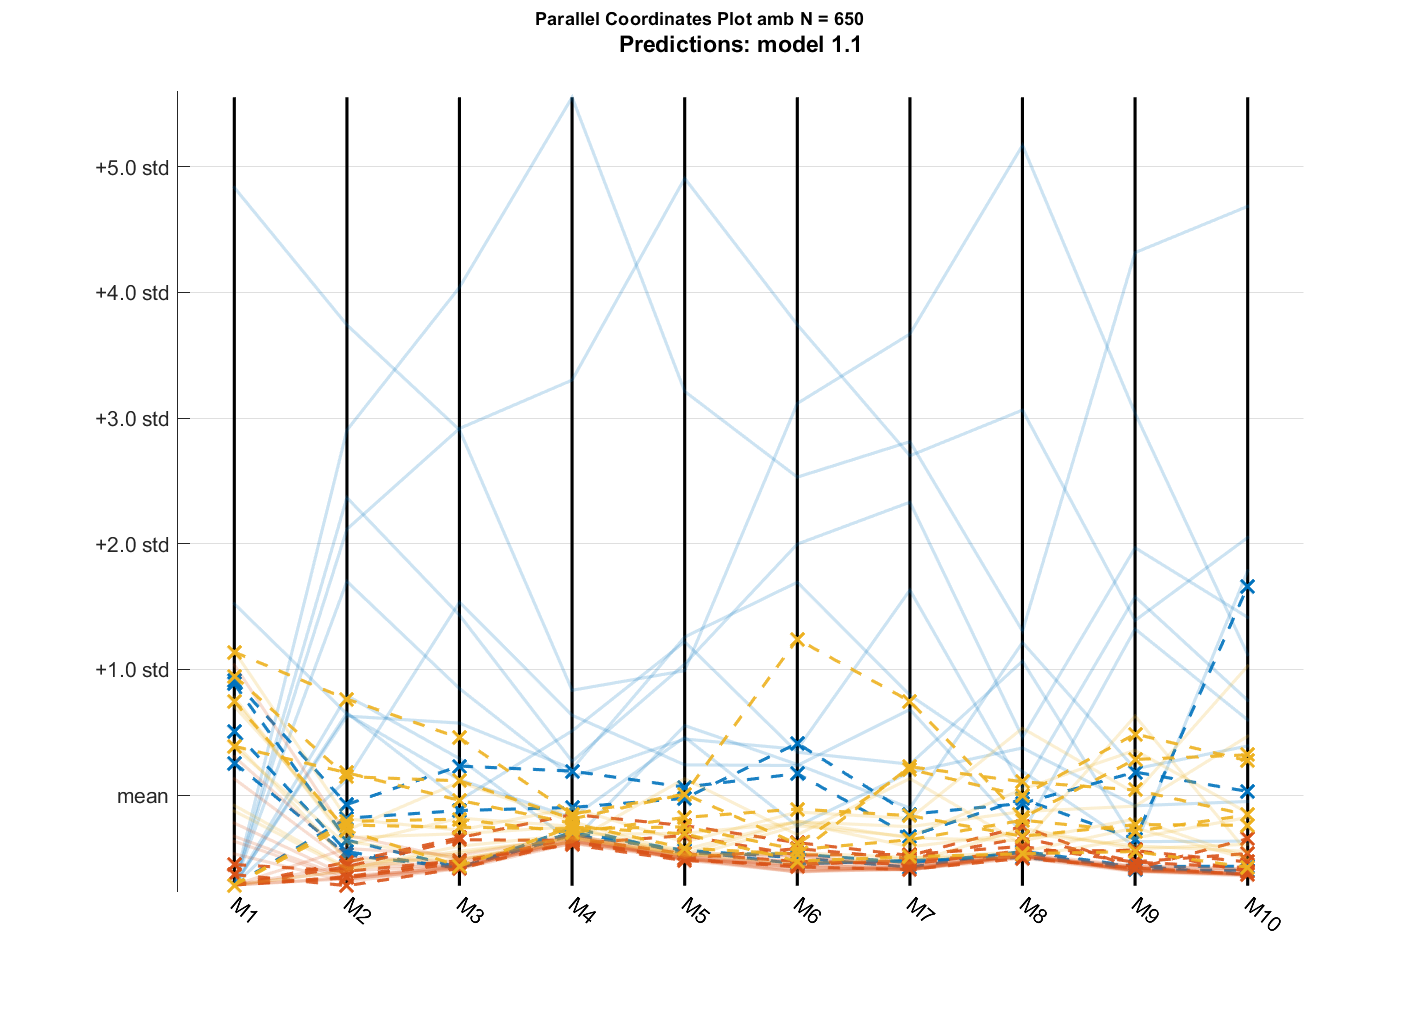

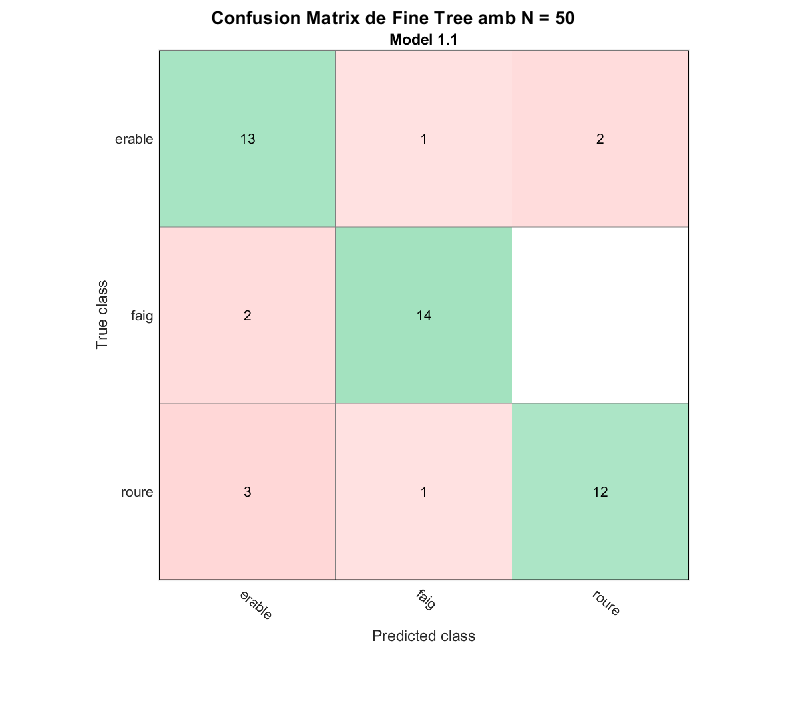

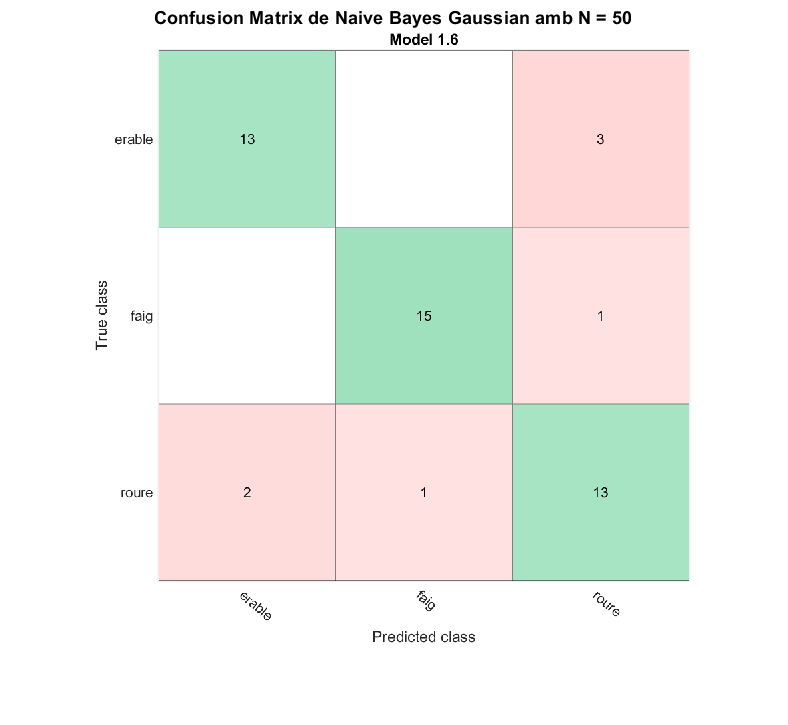

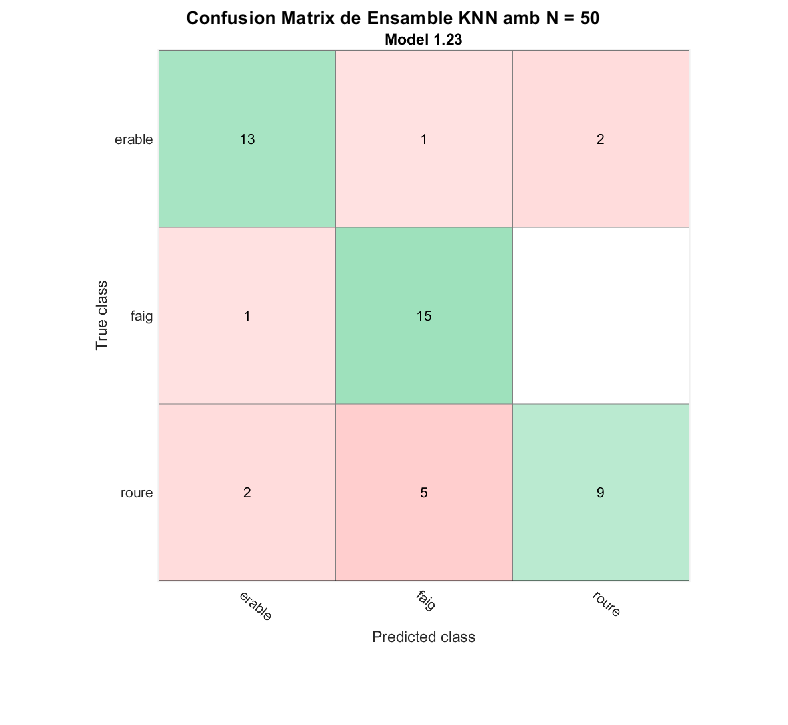

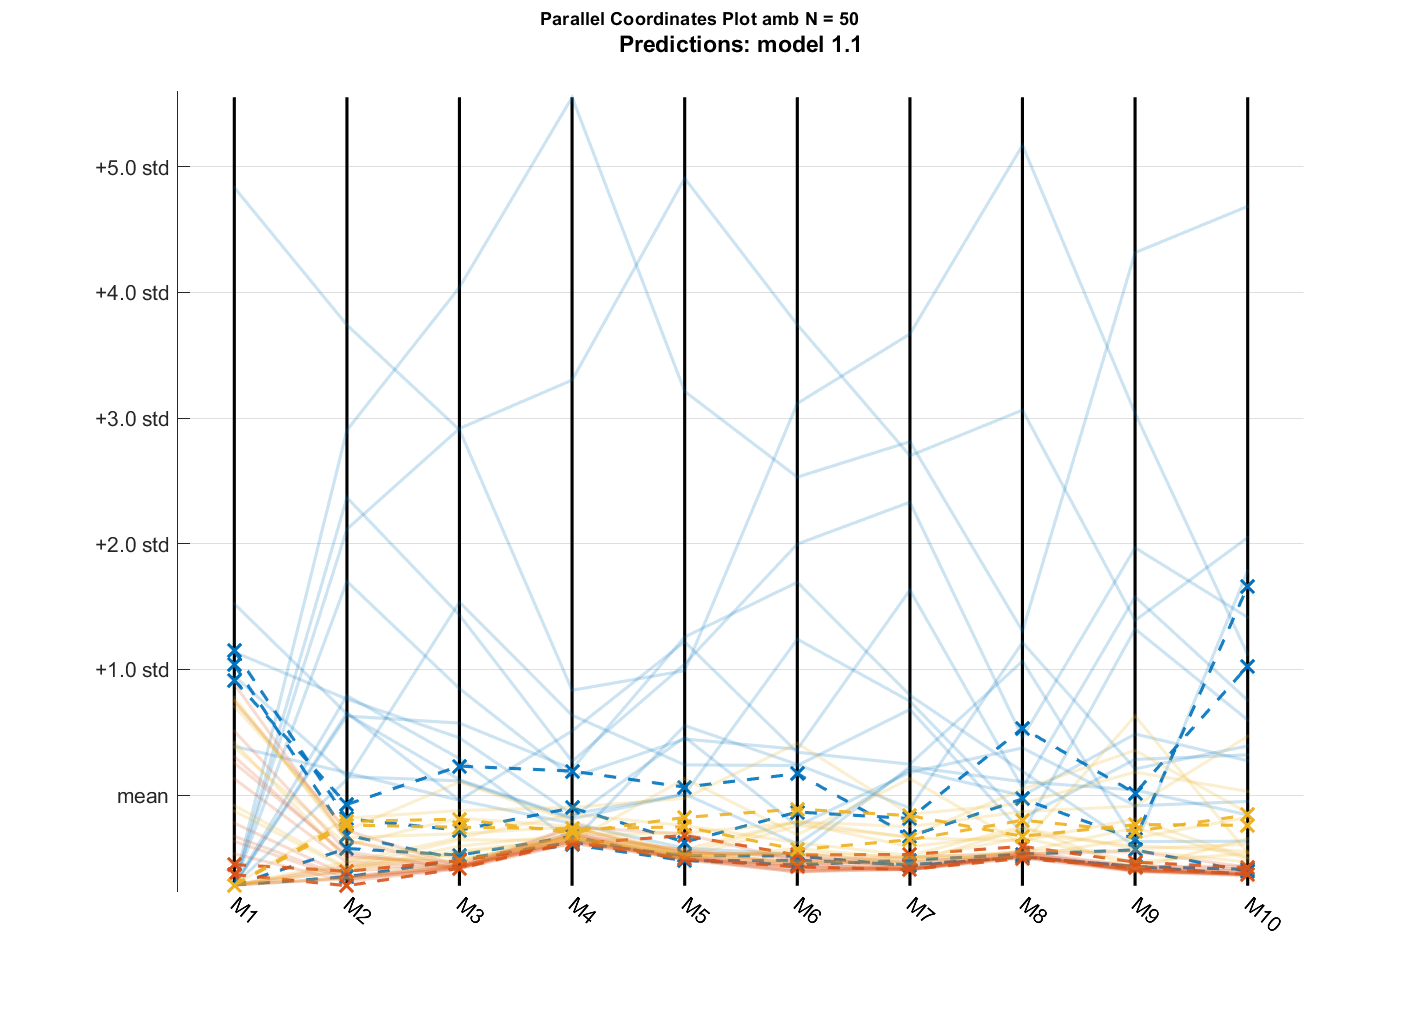

im = imread("ConfusionTree50.png");
imshow(im);
title("Confusion Matrix de Fine Tree amb N = 50");

im = imread("ConfusionBayes50.png");
imshow(im);
title("Confusion Matrix de Naive Bayes Gaussian amb N = 50");

im = imread("ConfusionEnsamble50.png");
imshow(im);
title("Confusion Matrix de Ensamble KNN amb N = 50");

im = imread("ParallelTree50.png");
imshow(im);
title("Parallel Coordinates Plot amb N = 50");